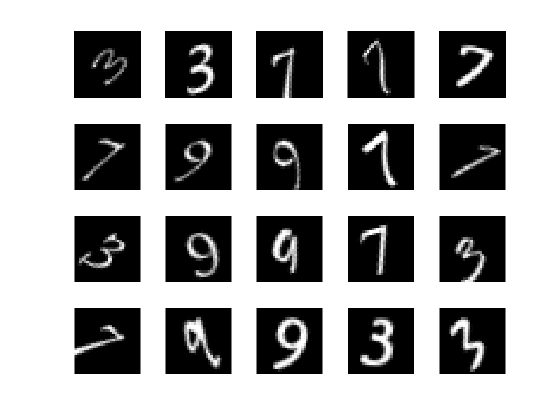

% Load the training data into memory
[xTrainImages,tTrain] = digitTrainCellArrayData;

% Display some of the training images
clf
for i = 1:20
    subplot(4,5,i);
    imshow(xTrainImages{i});
end

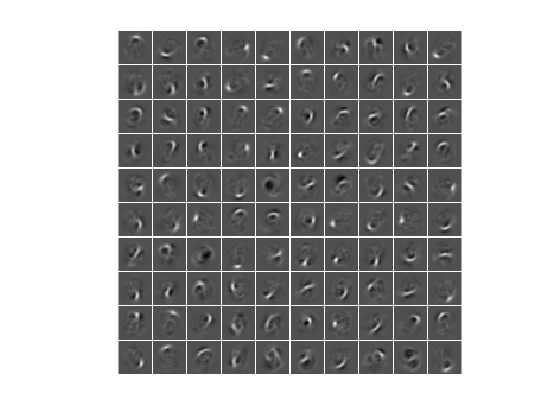


rng('default')

hiddenSize1 = 100;

autoenc1 = trainAutoencoder(xTrainImages,hiddenSize1, ...
    'MaxEpochs',400, ...
    'L2WeightRegularization',0.004, ...
    'SparsityRegularization',4, ...
    'SparsityProportion',0.15, ...
    'ScaleData', false);

view(autoenc1)

figure()
plotWeights(autoenc1);

feat1 = encode(autoenc1,xTrainImages);

hiddenSize2 = 50;
autoenc2 = trainAutoencoder(feat1,hiddenSize2, ...
    'MaxEpochs',100, ...
    'L2WeightRegularization',0.002, ...
    'SparsityRegularization',4, ...
    'SparsityProportion',0.1, ...
    'ScaleData', false);

view(autoenc2)

feat2 = encode(autoenc2,feat1);

softnet = trainSoftmaxLayer(feat2,tTrain,'MaxEpochs',400);


view(softnet)

view(autoenc1)
view(autoenc2)
view(softnet)


deepnet = stack(autoenc1,autoenc2,softnet);

view(deepnet)

% Get the number of pixels in each image
imageWidth = 28;
imageHeight = 28;
inputSize = imageWidth*imageHeight;


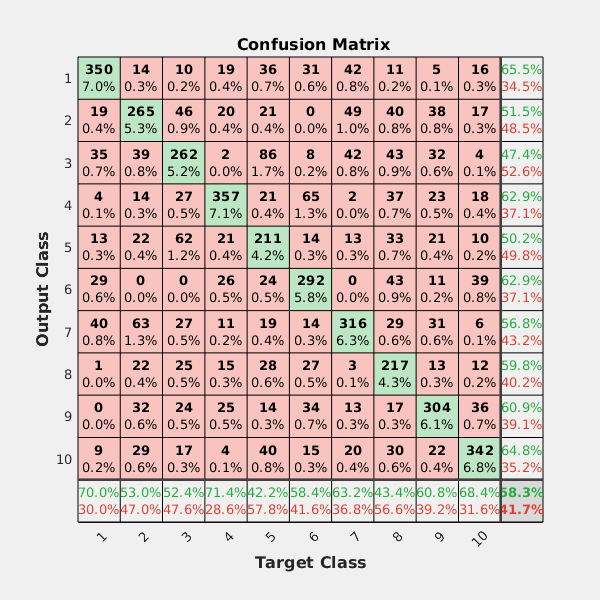

% Load the test images
[xTestImages,tTest] = digitTestCellArrayData;

% Turn the test images into vectors and put them in a matrix
xTest = zeros(inputSize,numel(xTestImages));
for i = 1:numel(xTestImages)
    xTest(:,i) = xTestImages{i}(:);
end

y = deepnet(xTest);
plotconfusion(tTest,y);

% Turn the training images into vectors and put them in a matrix
xTrain = zeros(inputSize,numel(xTrainImages));
for i = 1:numel(xTrainImages)
    xTrain(:,i) = xTrainImages{i}(:);
end


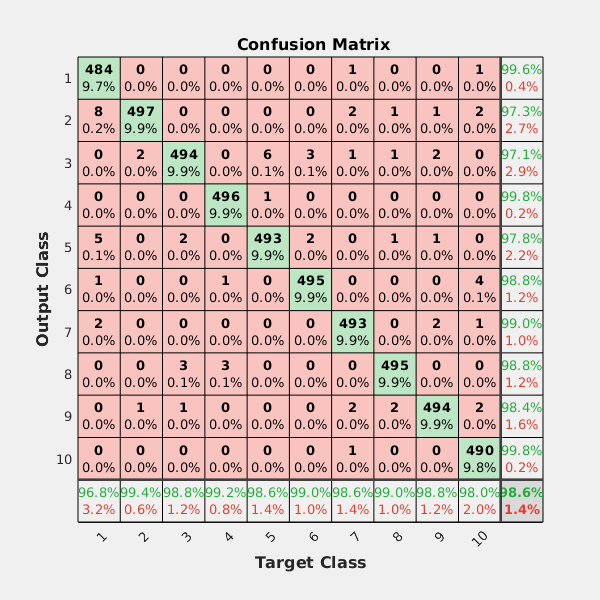

% Perform fine tuning
deepnet = train(deepnet,xTrain,tTrain);

y = deepnet(xTest);
plotconfusion(tTest,y);